**Create 2-D Geometry in PDE Modeler App**

Create a geometry in the PDE Modeler app. First, open the PDE Modeler app with a geometry consisting of a rectangle and 12 circles.

% pderect([0 0.01 0 0.008])
% for i = 0.002:0.003:0.009
%    for j = 0.002:0.003:0.006
%        pdecirc(i,j,0.0005)
%    end
% end

Geometry in 2D

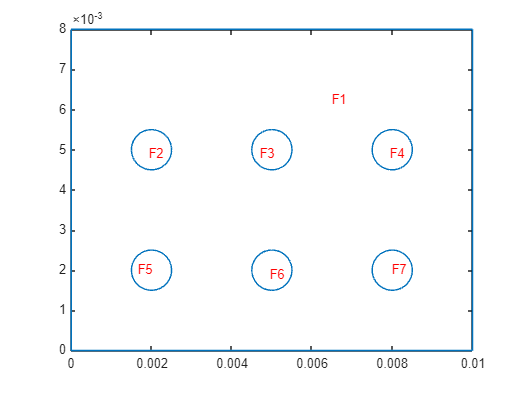

g = decsg(gd,sf,ns);
pdegplot(g,FaceLabels="on")

Create a 2-D geometry from the decomposed geometry matrix.

g = fegeometry(g)

g =   fegeometry with properties:

       NumFaces: 7
       NumEdges: 28
    NumVertices: 28
       NumCells: 0
       Vertices: [28×2 double]
           Mesh: []


Extrude the 2-D geometry along the *z*-axis by 0.0005 units.

g = extrude(g,0.0005);

Plot the extruded geometry so that you can see the face labels on the top.

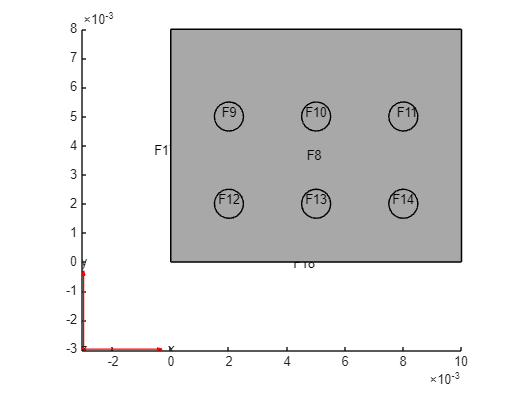

figure
pdegplot(g,FaceLabels="on")
view([0 90])

Extrude the circular faces (faces with IDs from 9 to 14) along the *z*-axis by 0.005 more units. These faces form the fins of the heat sink.

g = extrude(g,[9:14],0.005);

Plot the geometry.    

g

g =   fegeometry with properties:

       NumFaces: 72
       NumEdges: 132
    NumVertices: 80
       NumCells: 13
       Vertices: [80×3 double]
           Mesh: []


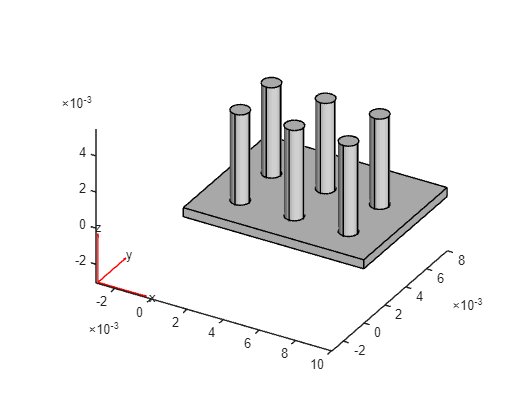


figure
pdegplot(g)

**Perform Thermal Analysis**

Create an `femodel` object for transient thermal analysis and include the geometry.

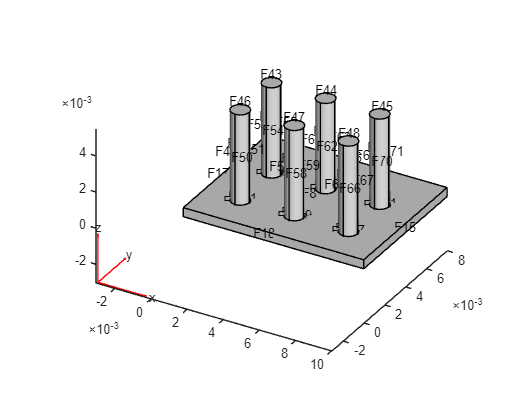

model = femodel(AnalysisType="thermalTransient", ...
                Geometry = g);

pdegplot(g, FaceLabels="on")

Assuming that the heat sink is made of copper, specify the thermal conductivity, mass density, and specific heat.

model.MaterialProperties = ...
    materialProperties(ThermalConductivity=400, ...
                       MassDensity=8960, ...
                       SpecificHeat=386);

Specify the Stefan-Boltzmann constant.

model.StefanBoltzmann = 5.670367e-8;

Apply the temperature boundary condition on the bottom surface of the heat sink, which consists of 8 faces.

% model.FaceBC(1:7) = faceBC(Temperature=1);
% model.FaceBC(1:18) = faceBC(Temperature=1000);
model.FaceBC(1:7) = faceBC(Temperature=1000);

Specify the convection and radiation parameters on all other surfaces of the heat sink.

% model.FaceLoad(8:g.NumFaces) = ...
%     faceLoad(ConvectionCoefficient=0, ...
%              AmbientTemperature=1, ...
%              Emissivity=0);
% model.FaceLoad(8:g.NumFaces) = ...
%     faceLoad(ConvectionCoefficient=5, ...
%              AmbientTemperature=300, ...
%              Emissivity=0.8);
model.FaceLoad(8:g.NumFaces) = ...
    faceLoad(ConvectionCoefficient=0, ...
             AmbientTemperature=300, ...
             Emissivity=0);

Set the initial temperature of all the surfaces to the ambient temperature.

% model.CellIC = cellIC(Temperature=0);
model.CellIC = cellIC(Temperature=300);

Generate a mesh.

model = generateMesh(model, GeometricOrder="linear")

model =   1×1 femodel array

Properties for analysis type: thermalTransient

            AnalysisType: "thermalTransient"
                Geometry: [1×1 fegeometry]
      MaterialProperties: [1×13 materialProperties]

   Boundary Conditions
                  FaceBC: [1×72 faceBC]
                  EdgeBC: [0×132 edgeBC]
                VertexBC: [0×80 vertexBC]
        ThermalRadiation: []

   Loads
                CellLoad: [0×13 cellLoad]
                FaceLoad: [1×72 faceLoad]
                EdgeLoad: [0×132 edgeLoad]
              VertexLoad: [0×80 vertexLoad]

   Initial Conditions
                  CellIC: [1×13 cellIC]
                  FaceIC: [0×72 faceIC]
                  EdgeIC: [0×132 edgeIC]
                VertexIC: [0×80 vertexIC]

   Other Parameters
            DampingAlpha: 0
             DampingBeta: 0
    ReferenceTemperature: []
           SolverOptions: [1×1 pde.PDESolverOptions]

   Constants


model.Mesh

ans =   FEMesh with properties:

             Nodes: [3×4826 double]
          Elements: [4×17875 double]
    MaxElementSize: 5.1264e-04
    MinElementSize: 2.5632e-04
     MeshGradation: 1.5000
    GeometricOrder: 'linear'


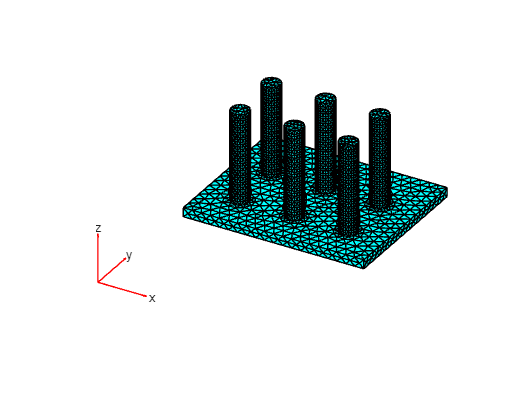

pdemesh(model)

### get Nodes on Face

(Lấy ra ma trận các Node trên mỗi mặt của vật thể (Các vị trí ở biên))

nodesOnFace1 = findNodes(model.Mesh, 'region', 'Face', 1)

nodesOnFace1 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50



nodesOnFace2 = findNodes(model.Mesh, 'region', 'Face', 2)

nodesOnFace2 =           17          18          19          20          21          22          23          24          25          26          27          28        2056        2057        2058        2059



nodesOnFace3 = findNodes(model.Mesh, 'region', 'Face', 3)

nodesOnFace3 =           41          42          43          44          45          46          47          48          49          50          51          52        2060        2061        2062        2063



nodesOnFace4 = findNodes(model.Mesh, 'region', 'Face', 4)

nodesOnFace4 =           65          66          67          68          69          70          71          72          73          74          75          76        2064        2065        2066        2067



nodesOnFace5 = findNodes(model.Mesh, 'region', 'Face', 5)

nodesOnFace5 =            5           6           7           8           9          10          11          12          13          14          15          16        2068        2069        2070        2071



nodesOnFace6 = findNodes(model.Mesh, 'region', 'Face', 6)

nodesOnFace6 =           29          30          31          32          33          34          35          36          37          38          39          40        2072        2073        2074        2075        2076



nodesOnFace7 = findNodes(model.Mesh, 'region', 'Face', 7)

nodesOnFace7 =           53          54          55          56          57          58          59          60          61          62          63          64        2077        2078        2079        2080        2081



Node_boundary = [nodesOnFace1, nodesOnFace2];
Node_boundary = unique(Node_boundary)

Node_boundary =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


### **get the matrix of Element**

(Lấy ra ma trận các phần tử)

Mesh_Mt = (model.Mesh.Elements)'

Mesh_Mt =         1934        1835        2189        1834
        2354        2373        2283        2023
        1754         238        2466         239
        2460        2111        1741         325
        1801         270         269        2472
        1960        2128        1789        1788
        3916        2348        2342        2253
        2112         293        2480         294
        2196        1938        1841        1842
         369        1843         368        2194


### **get the matrix of Nodes**

(Lấy ra ma trận các node)

Node_Mt = (model.Mesh.Nodes)'

Node_Mt =     0.0100         0         0
    0.0100    0.0080         0
         0    0.0080         0
         0         0         0
    0.0015    0.0020         0
    0.0016    0.0018         0
    0.0017    0.0016         0
    0.0020    0.0015         0
    0.0022    0.0016         0
    0.0024    0.0018         0


### **Calculate the matrix M_local at each element and calculate the Matrix M_total in **$$\Omega$$

(Tính ma trận M)


$$\int_{\Omega} \phi_i  \phi_j \,dx\,dy\,dz$$


M_total = zeros(size(Node_Mt,1), size(Node_Mt,1));
M_local = zeros(4,4);
for i=1 : size(Mesh_Mt,1)
% i=3
    %syms g1 g2 g3 g4
    %g = [g1 g2 g3 g4]
    g = Mesh_Mt(i, :);
    g1 = Node_Mt(g(1),:);
    g2 = Node_Mt(g(2),:);
    g3 = Node_Mt(g(3),:);
    g4 = Node_Mt(g(4),:);
    % thay thế các điểm g1, g2, g3, g4 thành các điểm A_1, A_2, A_3, A_4 
    x1 = g1(1); y1= g1(2) ; z1 = g1(3); 
    x2 = g2(1); y2= g2(2) ; z2 = g2(3); 
    x3 = g3(1); y3= g3(2) ; z3 = g3(3); 
    x4 = g4(1); y4= g4(2) ; z4 = g4(3); 

    P = [1 x1 y1 z1;...
         1 x2 y2 z2;...
         1 x3 y3 z3;...
         1 x4 y4 z4];
    Q = inv(P);
                %{
                P1 = [1 g1 ; ...
                      1 g2 ; ...
                      1 g3 ; ...
                      1 g4]
                Q1 = inv(P1)
                Q- Q1
                J = [ 
                    ] 
                %}
    % Khi chuyển hệ tọa độ ban đầu sang hệ mới và tính tích phân ta thu
    % được các công thức tính tích phân ứng với từng phi_i*phi_j, 
    % ma trận M_local(4,4) là ma trận đối xứng
    % Tính các tích phân để đưa vào M_local
    % Tích phân trên miền e của phi_1*phi_1
    M_local(1,1) = abs(x1*y2*z3 - x1*y3*z2 - x2*y1*z3 + x2*y3*z1 + x3*y1*z2 - x3*y2*z1 - x1*y2*z4 + ...
        x1*y4*z2 + x2*y1*z4 - x2*y4*z1 - x4*y1*z2 + x4*y2*z1 + x1*y3*z4 - x1*y4*z3 - ...
        x3*y1*z4 + x3*y4*z1 + x4*y1*z3 - x4*y3*z1 - x2*y3*z4 + x2*y4*z3 + x3*y2*z4 - ...
        x3*y4*z2 - x4*y2*z3 + x4*y3*z2)/60 ;
    % Tích phân trên miền e của phi_1*phi_2 = phi_2*phi_1
    M_local(1,2) = abs(x1*y2*z3 - x1*y3*z2 - x2*y1*z3 + x2*y3*z1 + x3*y1*z2 - x3*y2*z1 - x1*y2*z4 + ...
        x1*y4*z2 + x2*y1*z4 - x2*y4*z1 - x4*y1*z2 + x4*y2*z1 + x1*y3*z4 - x1*y4*z3 - ...
        x3*y1*z4 + x3*y4*z1 + x4*y1*z3 - x4*y3*z1 - x2*y3*z4 + x2*y4*z3 + x3*y2*z4 - ...
        x3*y4*z2 - x4*y2*z3 + x4*y3*z2)/120 ;
    % Tích phân trên miền e của phi_1*phi_3 = phi_3*phi_1
    M_local(1,3) = abs(x1*y2*z3 - x1*y3*z2 - x2*y1*z3 + x2*y3*z1 + x3*y1*z2 - x3*y2*z1 - x1*y2*z4 + ...
        x1*y4*z2 + x2*y1*z4 - x2*y4*z1 - x4*y1*z2 + x4*y2*z1 + x1*y3*z4 - x1*y4*z3 - ...
        x3*y1*z4 + x3*y4*z1 + x4*y1*z3 - x4*y3*z1 - x2*y3*z4 + x2*y4*z3 + x3*y2*z4 - ...
        x3*y4*z2 - x4*y2*z3 + x4*y3*z2)/120 ;
    % Tích phân trên miền e của phi_1*phi_4 = phi_4*phi_1
    M_local(1,4) = abs(x1*y2*z3 - x1*y3*z2 - x2*y1*z3 + x2*y3*z1 + x3*y1*z2 - x3*y2*z1 - x1*y2*z4 + ...
        x1*y4*z2 + x2*y1*z4 - x2*y4*z1 - x4*y1*z2 + x4*y2*z1 + x1*y3*z4 - x1*y4*z3 - ...
        x3*y1*z4 + x3*y4*z1 + x4*y1*z3 - x4*y3*z1 - x2*y3*z4 + x2*y4*z3 + x3*y2*z4 - ...
        x3*y4*z2 - x4*y2*z3 + x4*y3*z2)/120 ;
    % Tích phân trên miền e của phi_2*phi_2 
    M_local(2,2) = abs(x1*y2*z3 - x1*y3*z2 - x2*y1*z3 + x2*y3*z1 + x3*y1*z2 - x3*y2*z1 - x1*y2*z4 + ...
        x1*y4*z2 + x2*y1*z4 - x2*y4*z1 - x4*y1*z2 + x4*y2*z1 + x1*y3*z4 - x1*y4*z3 - ...
        x3*y1*z4 + x3*y4*z1 + x4*y1*z3 - x4*y3*z1 - x2*y3*z4 + x2*y4*z3 + x3*y2*z4 - ...
        x3*y4*z2 - x4*y2*z3 + x4*y3*z2)/60 ;
    % Tích phân trên miền e của phi_2*phi_3 = phi_3*phi_2
    M_local(2,3) = abs(x1*y2*z3 - x1*y3*z2 - x2*y1*z3 + x2*y3*z1 + x3*y1*z2 - x3*y2*z1 - x1*y2*z4 + ...
        x1*y4*z2 + x2*y1*z4 - x2*y4*z1 - x4*y1*z2 + x4*y2*z1 + x1*y3*z4 - x1*y4*z3 - ...
        x3*y1*z4 + x3*y4*z1 + x4*y1*z3 - x4*y3*z1 - x2*y3*z4 + x2*y4*z3 + x3*y2*z4 - ...
        x3*y4*z2 - x4*y2*z3 + x4*y3*z2)/120 ;
    % Tích phân trên miền e của phi_2*phi_4 = phi_4*phi_2
    M_local(2,4) = abs(x1*y2*z3 - x1*y3*z2 - x2*y1*z3 + x2*y3*z1 + x3*y1*z2 - x3*y2*z1 - x1*y2*z4 + ...
        x1*y4*z2 + x2*y1*z4 - x2*y4*z1 - x4*y1*z2 + x4*y2*z1 + x1*y3*z4 - x1*y4*z3 - ...
        x3*y1*z4 + x3*y4*z1 + x4*y1*z3 - x4*y3*z1 - x2*y3*z4 + x2*y4*z3 + x3*y2*z4 - ...
        x3*y4*z2 - x4*y2*z3 + x4*y3*z2)/120 ;
    % Tích phân trên miền e của phi_3*phi_3 
    M_local(3,3) = abs(x1*y2*z3 - x1*y3*z2 - x2*y1*z3 + x2*y3*z1 + x3*y1*z2 - x3*y2*z1 - x1*y2*z4 + ...
        x1*y4*z2 + x2*y1*z4 - x2*y4*z1 - x4*y1*z2 + x4*y2*z1 + x1*y3*z4 - x1*y4*z3 - ...
        x3*y1*z4 + x3*y4*z1 + x4*y1*z3 - x4*y3*z1 - x2*y3*z4 + x2*y4*z3 + x3*y2*z4 - ...
        x3*y4*z2 - x4*y2*z3 + x4*y3*z2)/60 ;
    % Tích phân trên miền e của phi_3*phi_4 = phi_4*phi_3
    M_local(3,4) = abs(x1*y2*z3 - x1*y3*z2 - x2*y1*z3 + x2*y3*z1 + x3*y1*z2 - x3*y2*z1 - x1*y2*z4 + ...
        x1*y4*z2 + x2*y1*z4 - x2*y4*z1 - x4*y1*z2 + x4*y2*z1 + x1*y3*z4 - x1*y4*z3 - ...
        x3*y1*z4 + x3*y4*z1 + x4*y1*z3 - x4*y3*z1 - x2*y3*z4 + x2*y4*z3 + x3*y2*z4 - ...
        x3*y4*z2 - x4*y2*z3 + x4*y3*z2)/120 ;
    % Tích phân trên miền e của phi_4*phi_4
    M_local(4,4) = abs(x1*y2*z3 - x1*y3*z2 - x2*y1*z3 + x2*y3*z1 + x3*y1*z2 - x3*y2*z1 - x1*y2*z4 + ...
        x1*y4*z2 + x2*y1*z4 - x2*y4*z1 - x4*y1*z2 + x4*y2*z1 + x1*y3*z4 - x1*y4*z3 - ...
        x3*y1*z4 + x3*y4*z1 + x4*y1*z3 - x4*y3*z1 - x2*y3*z4 + x2*y4*z3 + x3*y2*z4 - ...
        x3*y4*z2 - x4*y2*z3 + x4*y3*z2)/60 ;

    M_local = M_local + (M_local)';
    M_local = M_local -0.5* diag(diag(M_local));
    M_total(g,g) = M_total(g,g) + M_local;
    % Gán các giá trị vào ma trận M_local
    %M_local(g(1),g(1))= Ans11; M_local(g(1),g(2))= Ans12; M_local(g(1),g(3))= Ans13; M_local(g(1),g(4))= Ans14;
    %M_local(g(2),g(1))= Ans12; M_local(g(2),g(2))= Ans22; M_local(g(2),g(3))= Ans23; M_local(g(2),g(4))= Ans24;
    %M_local(g(3),g(1))= Ans13; M_local(g(3),g(2))= Ans23; M_local(g(3),g(3))= Ans33; M_local(g(3),g(4))= Ans34;
    %M_local(g(4),g(1))= Ans14; M_local(g(4),g(2))= Ans24; M_local(g(4),g(3))= Ans34; M_local(g(3),g(4))= Ans44;
end
M_total

M_total = 1.0e-07 *

    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        

### **Calculate the matrix S_local at each element and calculate the Matrix S_total in **$$\Omega$$

Tính ma trận S:


$$\int_{\Omega} \nabla \phi_i  \nabla \phi_j \,dx\,dy\,dz$$


S_total = zeros(size(Node_Mt,1), size(Node_Mt,1));
S_local = zeros(4,4);
for i=1 : size(Mesh_Mt,1)
    % i=1
    g = Mesh_Mt(i, :);
    g1 = Node_Mt(g(1),:);
    g2 = Node_Mt(g(2),:);
    g3 = Node_Mt(g(3),:);
    g4 = Node_Mt(g(4),:);
    % thay thế các điểm g1, g2, g3, g4 thành các điểm A_1, A_2, A_3, A_4
    x1 = g1(1); y1= g1(2) ; z1 = g1(3); 
    x2 = g2(1); y2= g2(2) ; z2 = g2(3); 
    x3 = g3(1); y3= g3(2) ; z3 = g3(3); 
    x4 = g4(1); y4= g4(2) ; z4 = g4(3); 

    P = [1 x1 y1 z1;...
         1 x2 y2 z2;...
         1 x3 y3 z3;...
         1 x4 y4 z4];
    Q = inv(P);
    % Thể tích của miền e xác định bởi 4 điểm A_1, A_2, A_3, A_4
    V_e = (1/6)*abs(x1*y2*z3 - x1*y3*z2 - x2*y1*z3 + x2*y3*z1 + x3*y1*z2 - x3*y2*z1 - ...
        x1*y2*z4 + x1*y4*z2 + x2*y1*z4 - x2*y4*z1 - x4*y1*z2 + x4*y2*z1 + x1*y3*z4 - ...
        x1*y4*z3 - x3*y1*z4 + x3*y4*z1 + x4*y1*z3 - x4*y3*z1 - x2*y3*z4 + x2*y4*z3 + ...
        x3*y2*z4 - x3*y4*z2 - x4*y2*z3 + x4*y3*z2);

    % Tính tích phân tích của hai nabla của phi_i và phi_j trên miền e
    % Tính Gradient của các hàm phi
    % Tính tích hai hàm gradient của phi
    % syms x y z
    % phi_1 = [1, x, y, z]*Q(:,1)
    % grad_phi_1 = gradient(phi_1,[x,y,z])
    % dot(grad_phi_1, grad_phi_1)*1

    % tích gradient của phi_1 và phi_1
    S_local(1,1) = (1/6)*V_e*(Q([2:4],1)'*Q([2:4],1));
    % tích gradient của phi_1 và phi_2 = phi_2 phi_1
    S_local(1,2) = (1/6)*V_e*(Q([2:4],2)'*Q([2:4],1));
    % tích gradient của phi_1 và phi_3 = phi_3 phi_1
    S_local(1,3) = (1/6)*V_e*(Q([2:4],3)'*Q([2:4],1));
    % tích gradient của phi_1 và phi_4 = phi_4 phi_1
    S_local(1,4) = (1/6)*V_e*(Q([2:4],4)'*Q([2:4],1));
    % tích gradient của phi_2 và phi_2
    S_local(2,2) = (1/6)*V_e*(Q([2:4],2)'*Q([2:4],2));
    % tích gradient của phi_2 và phi_3 = phi_3 phi_2
    S_local(2,3) = (1/6)*V_e*(Q([2:4],3)'*Q([2:4],2));
    % tích gradient của phi_2 và phi_4 = phi_4 phi_2
    S_local(2,4) = (1/6)*V_e*(Q([2:4],4)'*Q([2:4],2));
    % tích gradient của phi_3 và phi_3
    S_local(3,3) = (1/6)*V_e*(Q([2:4],3)'*Q([2:4],3));
    % tích gradient của phi_3 và phi_4 = phi_4 phi_3
    S_local(3,4) = (1/6)*V_e*(Q([2:4],4)'*Q([2:4],3));
    % tích gradient của phi_4 và phi_4
    S_local(4,4) = (1/6)*V_e*(Q([2:4],4)'*Q([2:4],4));

    S_local = S_local + (S_local)';
    S_local = S_local -0.5* diag(diag(S_local));
    S_total(g,g) = S_total(g,g) + S_local;
end
S_total

S_total =     0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         

Solve the transient thermal problem for times between 0 and 0.0075 s with a time step of 0.0025 s.

results = solve(model,0:0.005:0.02);

Plot the temperature distribution for each time step.

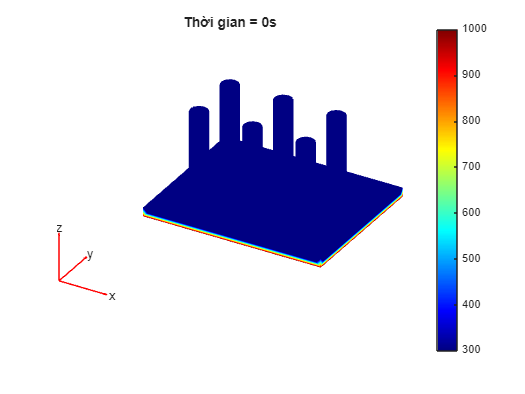

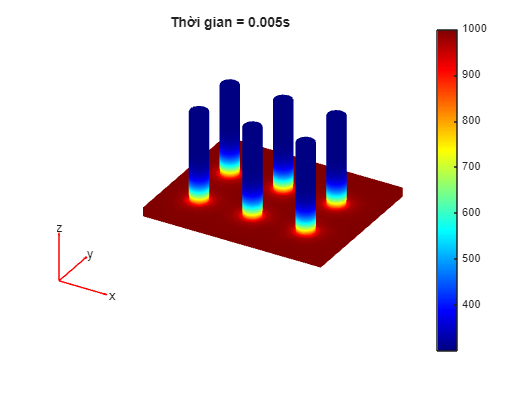

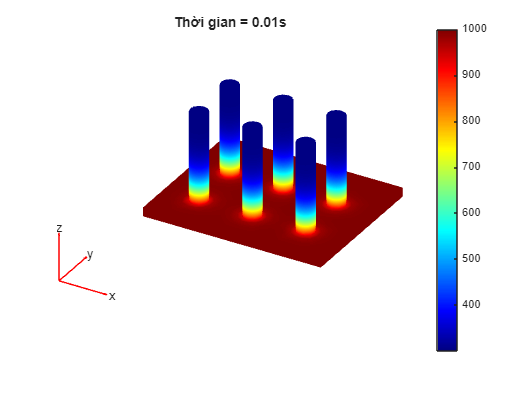

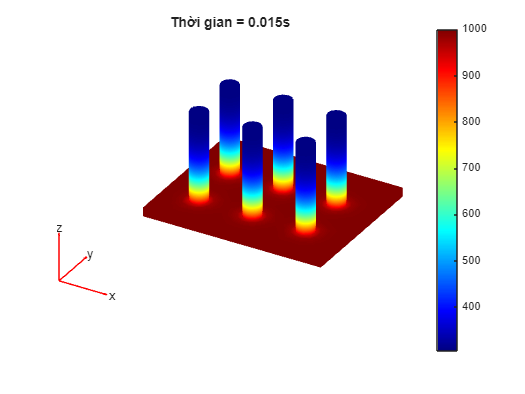

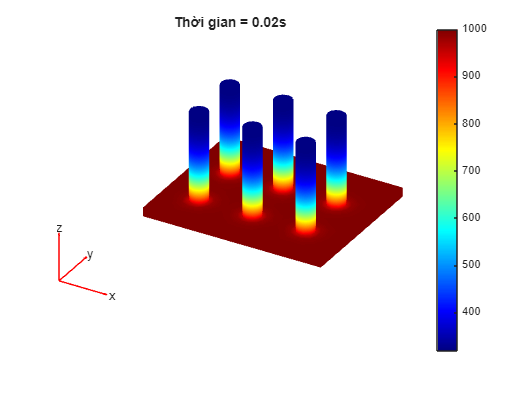

for i = 1:length(results.SolutionTimes)
  figure
  pdeplot3D(results.Mesh,ColorMapData=results.Temperature(:,i))
  title({['Thời gian = ' num2str(results.SolutionTimes(i)) 's']})
end